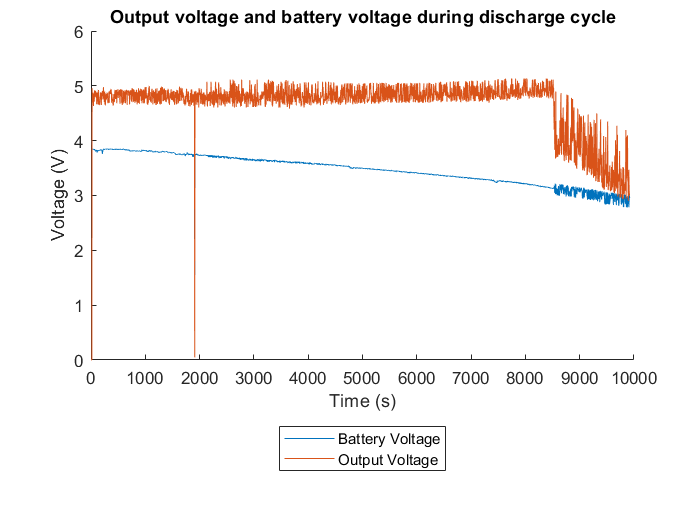

%Resistance of the power resitors in series that acted as the load.
R2 = 5;
R1 = 5;

figure(1)

hold on 

%to convert from time adc reading to voltage
BatteryVoltage = (ADCReading)*(5/1023);
BatteryVoltageSeries = timeseries(BatteryVoltage,time/1000);
plot(BatteryVoltageSeries)

OutputVoltage = (ADCReading1)*(5/1023);
OutputVoltage = OutputVoltage *((R2+R1)/R2);

%the output voltage was not measured over the full resistance as this could
%cause the adc to saturate at 5V if the output went higher than 5V.
%To caluclated the full output voltage the voltage divider equation was used.
%This gives

OutputVoltageSeries = timeseries(OutputVoltage,time/1000);
plot(OutputVoltageSeries)

title("Output voltage and battery voltage during discharge cycle")
xlabel("Time (s)")
ylabel('Voltage (V)')

legend('Battery Voltage','Output Voltage' )
 legend('Location','southoutside')



%to calculate the power that was disapated.
%The load restance was set to 55Ohm. Therefore we can use P = V^2/R to
%Calculate the instantaneous power using P=V^2/R
Power = (OutputVoltage.^2)/(R1+R2);
PowerSeries = timeseries(Power,time);
hold off

figure (2)
plot(PowerSeries)

%to calculate the actual capacity of the battery the area under the power
%plot was calculated.

WattHours = trapz(1/720,Power)

WattHours = 6.0751

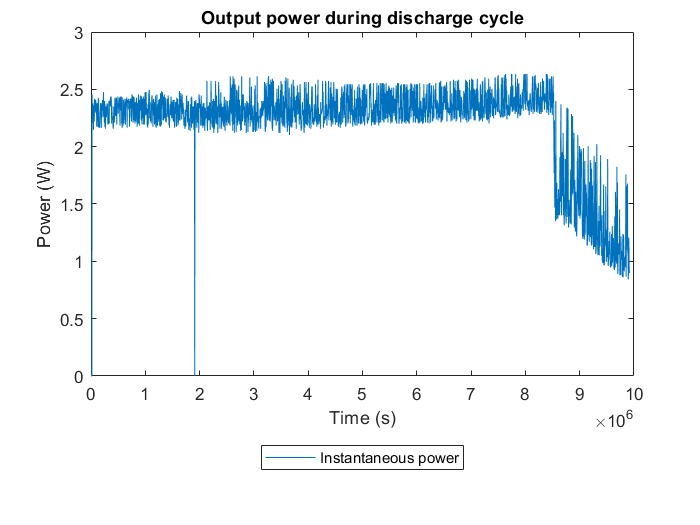


title("Output power during discharge cycle")
xlabel("Time (s)")
ylabel('Power (W)')

legend('Instantaneous power' )
 legend('Location','southoutside')